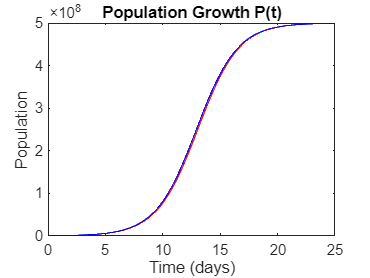

% Parameters
r = 0.56;
K = 5e8;
P0 = 3000 * 120;
total_days = 25;
dt_values = [1/24, 1/1440, 1/86400];
colors = ['r', 'g', 'b'];
pop_at_3_days = zeros(length(dt_values), 1);
figure1 = figure; figure2 = figure;

% Run simulations for each dt
for i = 1:length(dt_values)
    dt = dt_values(i);
    num_steps = ceil(total_days / dt);
    t = (0:num_steps) * dt;
    P = P0 * ones(1, num_steps+1);
    
    for n = 1:num_steps
        P(n + 1) = P(n) + dt * r * P(n) * (1 - P(n) / K);
        if abs(t(n) - 3) < dt
            pop_at_3_days(i) = P(n);
        end
    end
    
    % Plot population growth and growth rate
    figure(figure1); plot(t, P, colors(i)); hold on;
    figure(figure2); plot(t, r * P .* (1 - P / K), colors(i)); hold on;
end

% Annotations for plots
figure(figure1); title('Population Growth P(t)'); xlabel('Time (days)'); ylabel('Population');

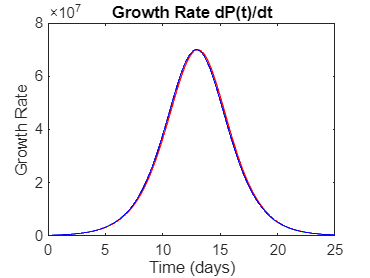

figure(figure2); title('Growth Rate dP(t)/dt'); xlabel('Time (days)'); ylabel('Growth Rate');


% Display population at 3 days and errors
P_3days = pop_at_3_days;
fprintf('The population of cells at 3 days for dt = 1/24 (hours): %.2f cells\n', P_3days(1));

The population of cells at 3 days for dt = 1/24 (hours): 1932921.32 cells


fprintf('The population of cells at 3 days for dt = 1/1440 (minutes): %.2f cells\n', P_3days(2));

The population of cells at 3 days for dt = 1/1440 (minutes): 1924923.78 cells


fprintf('The population of cells at 3 days for dt = 1/86400 (seconds): %.2f cells\n', P_3days(3));

The population of cells at 3 days for dt = 1/86400 (seconds): 1925549.80 cells


error1 = abs(P_3days(1) - P_3days(3)) / P_3days(3) * 100;
error2 = abs(P_3days(2) - P_3days(3)) / P_3days(3) * 100;
fprintf('The population of cells at 3 days for dt = 1/24 has an error of: %.2f%%\n', error1);

The population of cells at 3 days for dt = 1/24 has an error of: 0.38%


fprintf('The population of cells at 3 days for dt = 1/1440 has an error of: %.2f%%\n', error2);

The population of cells at 3 days for dt = 1/1440 has an error of: 0.03%



% Run the Simulink model 
simOut = sim('HW1simulink');

% Extract logged data from Simulink
loggedData_P = simOut.simout1; % Population data
loggedData_dPdt = simOut.simout; % Growth rate data

% Extract and check data format
time = linspace(0, total_days, length(loggedData_P))';
if size(loggedData_P, 2) == 2
    time = loggedData_P(:, 1);
    P_values = loggedData_P(:, 2);
else
    P_values = loggedData_P;
end
dPdt_values = loggedData_dPdt(:, end); % Last column for rate of change values

% Parameters
growth_rate = 0.56; % Growth rate (cells per day)
carrying_capacity = 5e8; % Carrying capacity (cells)
simulation_duration = 8; % Time interval (days)
time_step = 1/1440; % Time step in days (1 minute)
iterations = round(simulation_duration / time_step); % Defines number of steps in the iteration

% Creates an array with possible seedings
initial_population_array = 120 * (170500:500:180500); 

% Creates array that holds values of population
population_array = zeros(1, iterations);

% Loop through each possible initial seeding density
for index = 1:length(initial_population_array)
    initial_population = initial_population_array(index); % Initial population

    % Iterative loop that determines each population value
    for step = 1:iterations 
        population_array(step) = initial_population;
        growth_rate_step = growth_rate * initial_population * (1 - initial_population / carrying_capacity);
        initial_population = initial_population + time_step * growth_rate_step;
    end

    % Check if the population at the end of the time interval is within the specified tolerance
    if abs(population_array(end) - 0.8 * carrying_capacity) / (0.8 * carrying_capacity) < 0.0025
        fprintf('With a seeding of %d cells/cm^2 \n', initial_population_array(index) / 120);
        fprintf('The cell population in 8 days is: %d\n', population_array(end));
        fprintf('or an error of %.2f%%\n', 100 * abs(population_array(end) - 0.8 * carrying_capacity) / (0.8 * carrying_capacity));
        break;
    end
end

With a seeding of 179000 cells/cm^2 


The cell population in 8 days is: 3.991554e+08


or an error of 0.21%
